clc; clear; close all;

%[lyd,Fs] = audioread("﻿/Users/caspertk/Library/CloudStorage/OneDrive-AalborgUniversitet/4. semester/Projekt/Kode/ingridfinder7roedehuse.wav")
[lyd,Fs] = audioread("/Users/caspertk/Desktop/ingridfinder7roedehuse.wav")

lyd =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Fs = 44100

%[lyd,Fs] = audioread("/Users/caspertk/Downloads/P2 - kode osv/Experiment_Optagelser_ægte.wav")
nylyd = downsample(lyd, 3);


## Opsætning af variable

cutoff = 1500 %beta i projektet

cutoff = 1500

tfaktor = 1000 %tau i projektet

tfaktor = 1000

alpha = [1, 0.5, 0.7]

alpha =     1.0000    0.5000    0.7000


c = [500,3000]

c =          500        3000


## Opsætning af fft for signalet

%ori_fft = fft(nylyd,Fs/3)
ori_fft = fft(nylyd);
%plot(abs(ori1_fft))

original = abs(ori_fft(1:7350,:))

original =     1.1694
    0.6148
    1.0619
    0.6006
    0.7619
    0.8506
    0.8672
    0.2592
    0.8611
    0.7001


y1fft = ori_fft(1:c(1),:)

y1fft = 	1.0e+02 *

  -0.0117 + 0.0000i
  -0.0045 + 0.0042i
   0.0015 - 0.0105i
   0.0033 + 0.0050i
  -0.0025 - 0.0072i
   0.0084 + 0.0015i
  -0.0085 + 0.0016i
  -0.0017 - 0.0020i
  -0.0016 - 0.0085i
   0.0049 - 0.0050i


y2fft = ori_fft(cutoff+1:7350,:)

y2fft =   -2.8991 + 1.6151i
   4.5338 - 1.2871i
  -4.6842 + 4.5325i
   1.0652 - 6.5503i
   1.0570 + 3.5796i
  -3.0201 - 5.7101i
   6.2934 + 5.6244i
  -7.5208 + 0.0730i
   6.8239 - 2.6097i
  -5.8609 + 5.4367i


y3fft = zeros([cutoff 1])

y3fft =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y4fft = [zeros([cutoff 1]); y2fft]

y4fft =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i



y1 = abs(y1fft);
y2 = abs(y2fft);
y3 = abs(y3fft);
y4 = abs(y4fft);


N = length(original)

N = 7350



aliste = (zeros(N, 1));

for n = 1:N
    if n <= c(1)
        a = fix(alpha(1) * n);
        aliste(a) = aliste(a) + original(n);
        n1 = n;
    elseif (c(1) < n) && (n <= c(2))
        a = fix(alpha(2) * n + (alpha(1)*n1 - alpha(2)*n1)); % + 8
        aliste(a) = aliste(a) + original(n);
        n2 = n;
    else
        a = fix(alpha(3) * n + (n1 - alpha(2)*n1 + alpha(2)*n2 - alpha(3)*n2)); % - 16
        aliste(a) = aliste(a) + original(n);
    end
end

%﻿(a[0]*j1 - a[1]*j1)
%﻿(j1 - a[1]*j1 + a[1]*j2 - a[2]*j2)


lyden = aliste

lyden =     1.1694
    0.6148
    1.0619
    0.6006
    0.7619
    0.8506
    0.8672
    0.2592
    0.8611
    0.7001


%disp(lyden(1:7350,:))

lyden(5000)

ans = 0

%subplot(2,2,1)
plot(abs(original))
%xline(c(1),color='black',LineStyle='--',linewidth=1)
%title('Original signal')
xlim([0,7350])
xlabel('Frequency [Hz]', Fontsize = 18)
ylabel('Amplitude', Fontsize = 18)
lgd = legend('Original signal')

lgd =   Legend (Original signal) with properties:

         String: {'Original signal'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7161 0.8702 0.1750 0.0357]
          Units: 'normalized'

  Show all properties


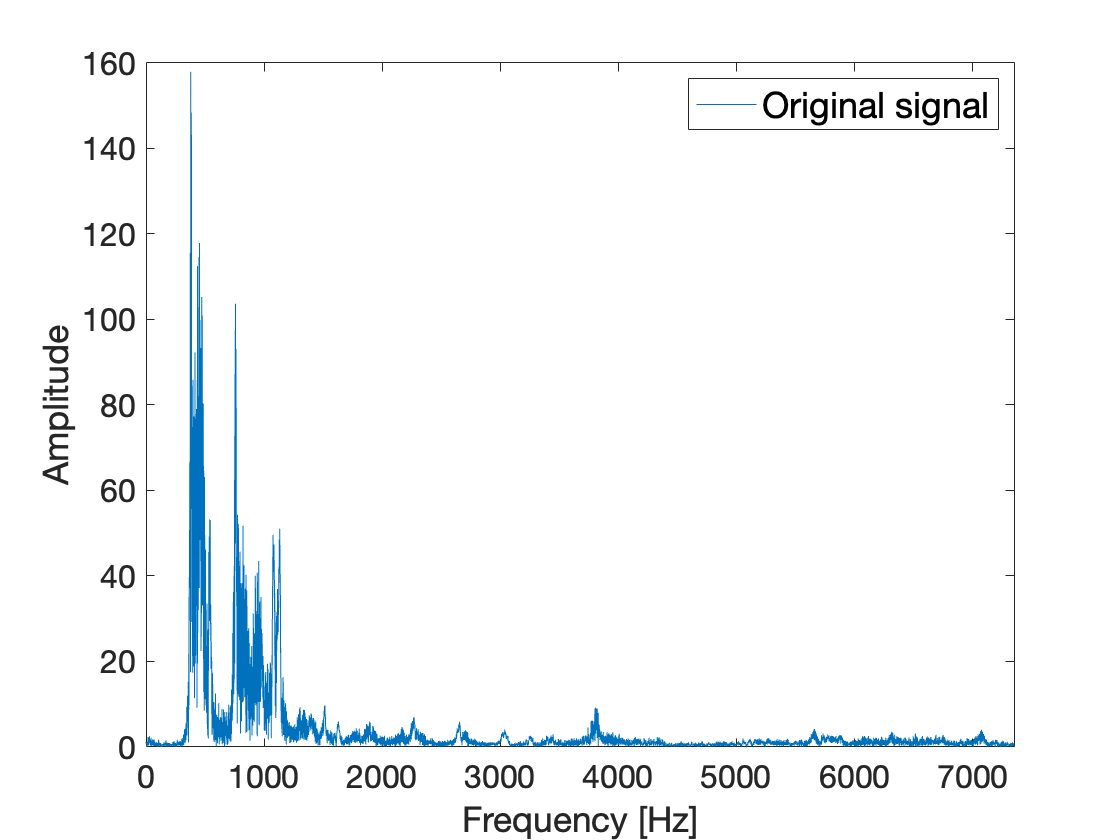

lgd.FontSize = 18;
set(gca, 'FontSize',16)
saveas(gcf,['/Users/caspertk/Library/CloudStorage/OneDrive-AalborgUniversitet/4. semester/Projekt/Kode/Lin_comp_plots1.png'])





%subplot(2,2,2)
plot(abs(original(1:500)))
hold on
green = [0.4660 0.8240 0.1880];
her1 = [zeros([500 1]); original([501:3000])];
%her1 = original(zeros(500, 1);original(501:3000),:)
plot(abs(her1), color=green)
hold on
her2 = [zeros([3000 1]); original([3001:7350])];
plot(abs(her2), color='red')
hold off
xline(c(1),color='black',LineStyle='--',linewidth=1)
xline(c(2),color='black',LineStyle='--',linewidth=1)
xlim([0,7350])
lgd = legend('Unchanged signal','Source Band', 'Source Band', 'Corner frequencies')

lgd =   Legend (Unchanged signal, Source Band, Source Band, Corner frequencies) with properties:

         String: {'Unchanged signal'  'Source Band'  'Source Band'  'Corner frequencies'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6804 0.7881 0.2107 0.1179]
          Units: 'normalized'

  Show all properties


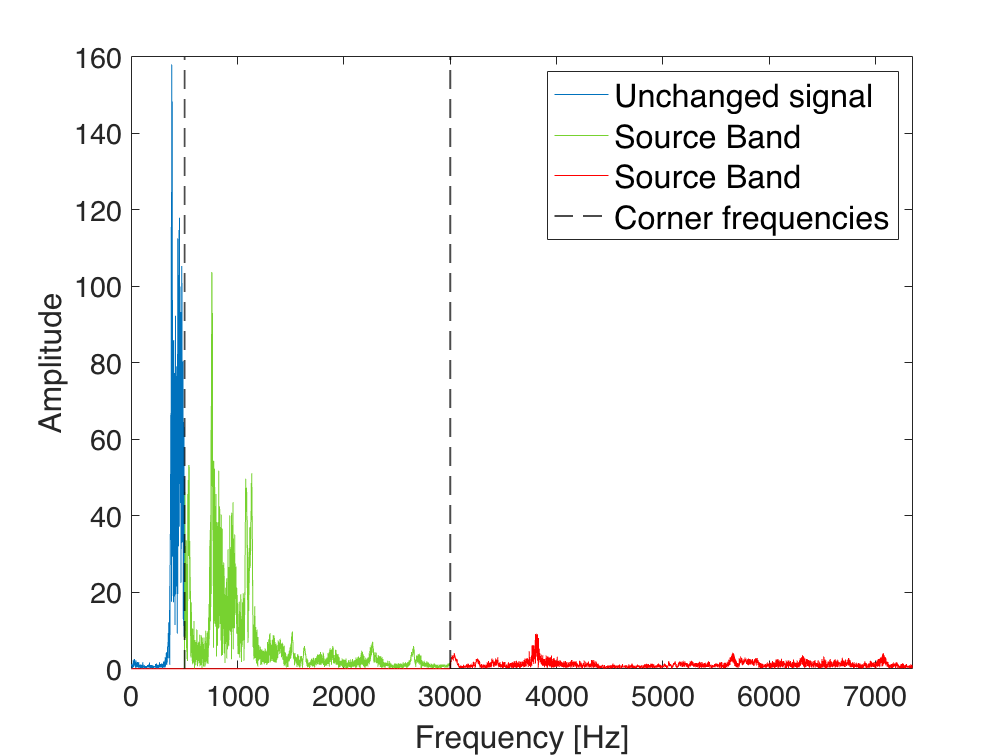

xlabel('Frequency [Hz]', FontSize = 18)
ylabel('Amplitude', FontSize = 18)
lgd.FontSize = 18;
set(gca, 'FontSize',16)
saveas(gcf,['/Users/caspertk/Library/CloudStorage/OneDrive-AalborgUniversitet/4. semester/Projekt/Kode/Lin_comp_plots2.png'])

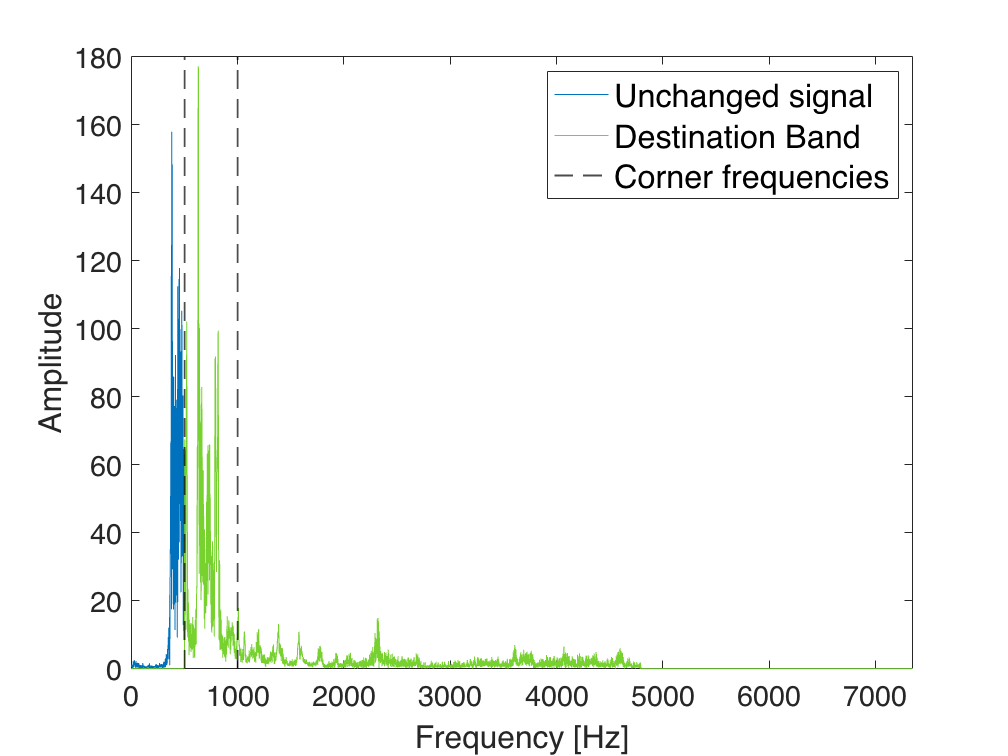




%subplot(2,2,[3 4])
green = [0.4660 0.8240 0.1880];

lyd1 = lyden(1:500,:);
lyd2 = [zeros([500 1]); lyden([501:1000])];
lyd3 = [zeros([1000 1]); lyden([1001:7350])];
lyd4 = [zeros([500 1]); lyden([501:7350])];
%plot(abs(lyden), color='red')
plot(abs(lyd1))
hold on
plot(abs(lyd4), color=green)
hold off
%plot(abs(lyd2), color=green)
%hold on
%plot(abs(lyd3), color=green)
%hold off
xline(c(1),color='black',LineStyle='--',linewidth=1)
xline(1000,color='black',LineStyle='--',linewidth=1)
xlim([0,7350])
legend('Unchanged signal','Destination Band','Corner frequencies', FontSize = 18)
xlabel('Frequency [Hz]', FontSize = 18)
ylabel('Amplitude', FontSize = 18)
set(gca, 'FontSize',16)
saveas(gcf,['/Users/caspertk/Library/CloudStorage/OneDrive-AalborgUniversitet/4. semester/Projekt/Kode/Lin_comp_plots3.png'])